# Numerical Solution of System of Linear Algebric Equations:

## Rank & Solution of system of algebric equations:

## Case-1: 


$$\begin{array}{l}
x+2y=1\\
x−y=4
\end{array}$$


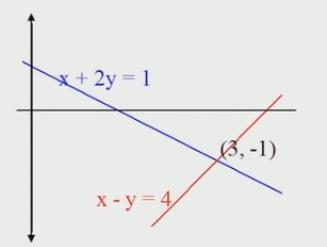.

Equivalent Matrix formulation of the set of equation: $\left\lbrack \begin{array}{c}
1 & 2\\
1 & −1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
4
\end{array}\right\rbrack$

We can Write this as, AX=B; where A=$\left\lbrack \begin{array}{c}
1 & 2\\
1 & −1
\end{array}\right\rbrack$, B=$\left\lbrack \begin{array}{c}
1\\
4
\end{array}\right\rbrack$ & X=$\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack$

Therefore X can be solved: X=$A^{−1} B$, It is clear from the graph that there is unique solution exist for these set of linear equations.

This conclusion can also be draw by checking the Rank of the matrix A

If rank(A)=number of rows/columns of the square matrix A, then unique solution will exist.

A_1=[1 2;1 -1];
B_1=[1;4];
[row,columns]=size(A_1)

row = 2

columns = 2

rank_A_1=rank(A_1)

rank_A_1 = 2

## In this case rows=rank of A, so unique solution exist.

To get the solution

X=A_1\B_1  % you can also use X=inv(A)*B;

X =      3
    -1


## Case-2: 


$$\begin{array}{l}
x+2y=1\\
2x+4y=4
\end{array}$$


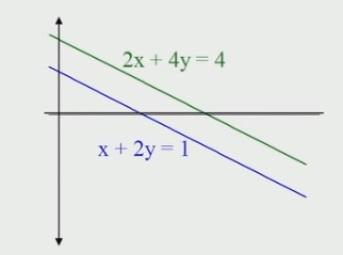.

Equivalent Matrix formulation of the set of equation: $\left\lbrack \begin{array}{c}
1 & 2\\
2 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
4
\end{array}\right\rbrack$

It is clear from the graph there is no solution for this set of equatons.

This can be shown in the following way

A_2=[1 2;2 4];
B_2=[1;4];
[row,columns]=size(A_2)

row = 2

columns = 2

rank_A_2=rank(A_2)

rank_A_2 = 1

## As Rank(A)<number of rows so there will not be unique solution.

In that case we ahve to form the augmented matrix Aug=[A B]

Then we have to find out rank of augmented matrix. 

If rank(Aug)$\ne$rank(A) then No solution  of the system of equations

If rank(Aug)=rank(A) then infinitely many solutions will exist

Check it for case-2

Aug_2=[A_2 B_2];
rank_Aug_2=rank(Aug_2)

rank_Aug_2 = 2

rank_A_2=rank(A_2)

rank_A_2 = 1

## In this case rank(Aug)$\ne$rank(A) therefore, there is no solution in this system of equations.

## Case-3: 


$$\begin{array}{l}
x+2y=1\\
2x+4y=2
\end{array}$$


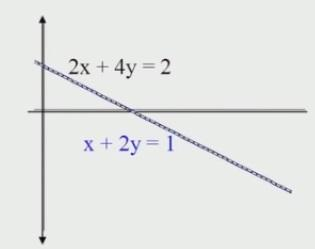.

Equivalent Matrix formulation of the set of equation: $\left\lbrack \begin{array}{c}
1 & 2\\
2 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack$

It is clear from the graph that there are infinitely many solutions exists

This can be shown in the following way

Compare number of rows & rank(A)

A_3=[1 2;2 4];
B_3=[1;2];
rank(A_3)

ans = 1

## Clear that rank(A)<number of rows.So no unique solution exist.

Compare rank of augmented matrix & rank of matrix A

Aug_3=[A_3 B_3];
rank(Aug_3)

ans = 1

rank(A_3)

ans = 1

Since rank of augmented matrix is equal to rank of A , 

## rank(Aug_3)=rank(A_3)=1 

## Therefore there are infinitely many solution exist for this case.

## Gauss Elimination (Algorithm)

Take one example: 


$$\begin{array}{l}
x_1 +x_2 +x_3 =4\\
{2x}_1 +x_2 +{3x}_3 =7\\
{3x}_1 +{4x}_2 {−2x}_3 =9
\end{array}$$


To solve this set of equations by Gauss Elimination

Form the coefficient matrix A, B matrix & augmented matrix Aug

A=[1 1 1;2 1 3;3 4 -2];
B=[4;7;9];
Aug=[A B]

Aug =      1     1     1     4
     2     1     3     7
     3     4    -2     9


In each step A(i,i) is the pivot element

Use pivot element to make zeros in pivot column

. $R_j =R_j −\alpha_{ij} R_i$, where $\alpha_{ij} =\frac{A\left(j,i\right)}{A\left(i,i\right)}$

Formation of upper triangular matrix

%A(1,1) as pivot element
alpha=Aug(2,1)/Aug(1,1);
Aug(2,:)=Aug(2,:)-alpha*Aug(1,:); % R2=R2-alpha*R1
alpha=Aug(3,1)/Aug(1,1);
Aug(3,:)=Aug(3,:)-alpha*Aug(1,:); % R3=R3-alpha*R1
Aug

Aug =      1     1     1     4
     0    -1     1    -1
     0     1    -5    -3



%A(2,2) as pivot element
alpha=Aug(3,2)/Aug(2,2);
Aug(3,:)=Aug(3,:)-alpha*Aug(2,:); % R3=R3-alpha*R2
Aug

Aug =      1     1     1     4
     0    -1     1    -1
     0     0    -4    -4


Back substitution:

. $x_3 =\frac{Aug\left(3,4\right)}{Aug\left(3,3\right)}$

. $x_2 =\frac{\text{Aug}\left(2,4\right)−\text{Aug}\left(2,3\right)∗x_3 }{\text{Aug}\left(2,2\right)}$

. $x_1 =\frac{\text{Aug}\left(1,4\right)−\text{Aug}\left(1,2\right)∗x_2 −\text{Aug}\left(1,3\right)∗x_3 }{\text{Aug}\left(1,1\right)}$

x=zeros(3,1);
x(3)=Aug(3,4)/Aug(3,3);
x(2)=(Aug(2,4)-Aug(2,3)*x(3))/Aug(2,2);
x(1)=(Aug(1,4)-Aug(1,2)*x(2)-Aug(1,3)*x(3))/Aug(1,1);
x

x =      1
     2
     1


## We can generalize the code in the following way

 %Define A, B & Aug=[A B]
A=[1 1 1;2 1 3;3 4 -2];
B=[4;7;9];
Aug=[A B]

Aug =      1     1     1     4
     2     1     3     7
     3     4    -2     9


% Find n  number of unknowns as rows =column in square matrix
[m,n]=size(A);
n

n = 3

% Gauss Elimination
for i=1:n-1
    for j=i+1:n
    alpha=Aug(j,i)/Aug(i,i);
    Aug(j,:)=Aug(j,:)-alpha*Aug(i,:); % Rj=Rj-alpha*Ri
    end
end
% Back Substitution
for i=n:-1:1
    x(i)=(Aug(i,end)-Aug(i,i+1:n)*x(i+1:n))/Aug(i,i);
end
x

x =      1
     2
     1


## Tri Diagonal Matrix Algorithm (TDMA)

Form of the matrices for n=7

$A=\left\lbrack \begin{array}{c}
d_1  & u_1  & 0 & 0 & 0 & 0 & 0\\
l_1  & d_2  & u_2  & 0 & 0 & 0 & 0\\
0 & l_2  & d_3  & u_3  & 0 & 0 & 0\\
0 & 0 & l_3  & d_4  & u_4  & 0 & 0\\
0 & 0 & 0 & l_4  & d_5  & u_5  & 0\\
0 & 0 & 0 & 0 & l_5  & d_6  & u_6 \\
0 & 0 & 0 & 0 & 0 & l_6  & d_7 
\end{array}\right\rbrack$; $B=\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 \\
b_4 \\
b_5 \\
b_6 \\
b_7 
\end{array}\right\rbrack$

## Example:  

Consider the following set of equations with variables $T_1 ,\text{ }T_2 ,\ldotp \ldotp \ldotp ,T_{10} ,T_{11}$

$\begin{array}{l}
T_1 =100\\
T_1 −\left(2+\alpha \right)T_2 +T_3 =\beta \\
T_2 −\left(2+\alpha \right)T_3 +T_4 =\beta \\
T_3 −\left(2+\alpha \right)T_4 +T_5 =\beta \\
\ldotp \\
\ldotp \\
T_9 −\left(2+\alpha \right)T_{10} +T_{11} =\beta \\
T_{11} =25
\end{array}$.

Consider $\beta$=-1, $\alpha$=0.04

If we arrange the equation in AT=B form, then A will be a TDM and T is a column matrix containing variables T1,T2,...

n=11

n = 11

A=zeros(11,11);
B=zeros(11,1);
alpha=0.04;
bita=-1;
d=-(2+alpha)

d = -2.0400

l=1;
u=1;
for i=2:n
    A(i,i)=d;
    A(i,i-1)=l;
    A(i-1,i)=u;
    B(i)=bita;
end
[A B]

ans =          0    1.0000         0         0         0         0         0         0         0         0         0         0
    1.0000   -2.0400    1.0000         0         0         0         0         0         0         0         0   -1.0000
         0    1.0000   -2.0400    1.0000         0         0         0         0         0         0         0   -1.0000
         0         0    1.0000   -2.0400    1.0000         0         0         0         0         0         0   -1.0000
         0         0         0    1.0000   -2.0400    1.0000         0         0         0         0         0   -1.0000
         0         0         0         0    1.0000   -2.0400    1.0000         0         0         0         0   -1.0000
         0         0         0         0         0    1.0000   -2.0400    1.0000         0         0         0   -1.0000
         0         0         0         0         0         0    1.0000   -2.0400    1.0000         0         0   -1.0000
         0         0      

A(1,1)=1;
A(11,11)=1;
A(1,2)=0;
A(11,10)=0;
B(1)=100;
B(11)=25;
AB=[A B]

AB =     1.0000         0         0         0         0         0         0         0         0         0         0  100.0000
    1.0000   -2.0400    1.0000         0         0         0         0         0         0         0         0   -1.0000
         0    1.0000   -2.0400    1.0000         0         0         0         0         0         0         0   -1.0000
         0         0    1.0000   -2.0400    1.0000         0         0         0         0         0         0   -1.0000
         0         0         0    1.0000   -2.0400    1.0000         0         0         0         0         0   -1.0000
         0         0         0         0    1.0000   -2.0400    1.0000         0         0         0         0   -1.0000
         0         0         0         0         0    1.0000   -2.0400    1.0000         0         0         0   -1.0000
         0         0         0         0         0         0    1.0000   -2.0400    1.0000         0         0   -1.0000
         0         0       


    
    T=A\B

T =   100.0000
   85.8589
   74.1521
   64.4114
   56.2471
   49.3327
   43.3917
   38.1863
   33.5084
   29.1708


## TDMA Algoritm to solve this problem


    for i=1:n-1
    %Normalize with respect to pivot element
    A(i,i+1)=A(i,i+1)/A(i,i);
    B(i)=B(i)/A(i,i);
    A(i,i)=1;
    % Elimination using pivot element
    alpha=A(i+1,i);
    A(i+1,i+1)=A(i+1,i+1)-alpha*A(i,i+1);
    B(i+1)=B(i+1)-alpha*B(i);
    A(i+1,i)=0;
end
AB=[A B]

AB =     1.0000         0         0         0         0         0         0         0         0         0         0  100.0000
         0    1.0000   -0.4902         0         0         0         0         0         0         0         0   49.5098
         0         0    1.0000   -0.6452         0         0         0         0         0         0         0   32.5911
         0         0         0    1.0000   -0.7170         0         0         0         0         0         0   24.0838
         0         0         0         0    1.0000   -0.7558         0         0         0         0         0   18.9594
         0         0         0         0         0    1.0000   -0.7787         0         0         0         0   15.5428
         0         0         0         0         0         0    1.0000   -0.7928         0         0         0   13.1159
         0         0         0         0         0         0         0    1.0000   -0.8018         0         0   11.3185
         0         0       

B;
% Back Substitution
T=zeros(n,1);
T(n)=B(n)/A(n,n);
for i=n-1:-1:1
    T(i)=B(i)-A(i,i+1)*T(i+1);
end
T

T =   100.0000
   85.8589
   74.1521
   64.4114
   56.2471
   49.3327
   43.3917
   38.1863
   33.5084
   29.1708


% Plot
plot([1:11],T,'LineWidth',2)

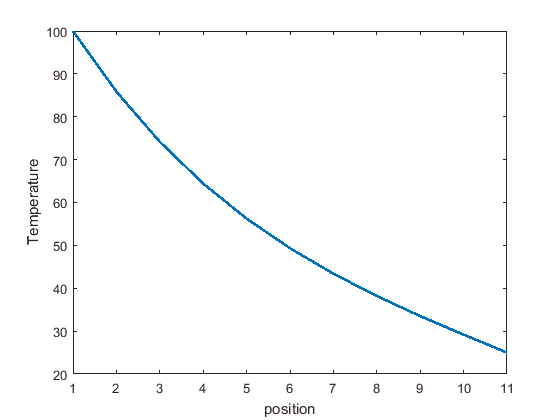

xlabel('position');
ylabel('Temperature');

## Iterative Methods of Solving Linear System of Equations of the form Ax=b

## Jacobi:


$$x_k^{\left(i+1\right)} =\frac{B_k −\left(\sum_{j\ne k} A_{k,j} x_j^{\left(i\right)} \right)}{A_{k,k} }$$


## Gauss Siedel:


$$x_k^{\left(i+1\right)} =\frac{B_k −\left(\sum_{j=1}^{k−1} A_{k,j} x_j^{\left(i+1\right)} +\sum_{k+1}^{n} A_{k,j} x_j^{\left(i\right)} \right)}{A_{k,k} }$$


## Example:


$$\begin{array}{l}
x_1 +x_2 +x_3 =4\\
{2x}_1 +x_2 +{3x}_3 =7\\
{3x}_1 +{4x}_2 {−2x}_3 =9
\end{array}$$


Solve this set of equations by Gauss Siedel Method:

Solution:

Order the equation based on diagonal dominance.


$${2x}_1 +x_2 +{3x}_3 =7$$



$${3x}_1 +{4x}_2 {−2x}_3 =9$$



$$x_1 +x_2 +x_3 =4$$


A=[2 1 3;3 4 -2;1 1 1];
B=[7;9;4];
AB=[A B];
n=3;

x=zeros(n,1);
err=zeros(n,1);
iter=25;
Err=zeros(iter,1);

% Gauss Siedel Iteration

for i=1:iter
    for k=1:n
        xold=x(k);
        x(k)=(AB(k,end)-AB(k,1:k-1)*x(1:k-1)-AB(k,k+1:n)*x(k+1:n))/AB(k,k);
        err(k)=abs(xold-x(k));
    end
   disp(['Iteration No. ',num2str(i),':  Error= ',num2str(max(err))]);
   Err(i)=max(err);  
end

Iteration No. 1:  Error= 3.5


Iteration No. 2:  Error= 1.2813


Iteration No. 3:  Error= 0.40625


Iteration No. 4:  Error= 0.38281


Iteration No. 5:  Error= 0.19727


Iteration No. 6:  Error= 0.14502


Iteration No. 7:  Error= 0.085571


Iteration No. 8:  Error= 0.057648


Iteration No. 9:  Error= 0.035805


Iteration No. 10:  Error= 0.023363


Iteration No. 11:  Error= 0.014792


Iteration No. 12:  Error= 0.0095388


Iteration No. 13:  Error= 0.0060827


Iteration No. 14:  Error= 0.0039054


Iteration No. 15:  Error= 0.002497


Iteration No. 16:  Error= 0.0016006


Iteration No. 17:  Error= 0.0010244


Iteration No. 18:  Error= 0.00065625


Iteration No. 19:  Error= 0.00042016


Iteration No. 20:  Error= 0.0002691


Iteration No. 21:  Error= 0.00017232


Iteration No. 22:  Error= 0.00011035


Iteration No. 23:  Error= 7.0668e-05


Iteration No. 24:  Error= 4.5256e-05


Iteration No. 25:  Error= 2.8981e-05


x

x =     1.0001
    2.0000
    1.0000


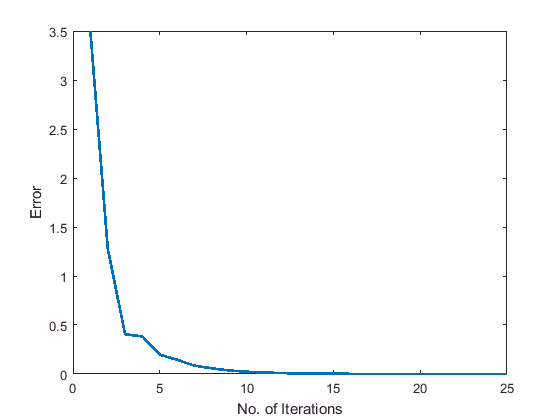

% Plot
plot([1:iter],Err,'LineWidth',2) 
xlabel('No. of Iterations');
ylabel('Error');

## Assignment: 

## Write MATLAB code for Jacobi Iteration to solve the same set of equations and show the convergence rate of the solution by plotting errors.